## Question

Our group engaged in question prompt 3: what public health measures would be most effective in fighting the flu? This is an interesting question because it may not be completely obvious as to how effective any given health measure will be, and it is valuable because public health officials should take into account the effectiveness and the difficulty of implementing such.

Furthermore, the public health measures we will be comparing are mask wearing, frequent handwashing, and vaccination. The comparative effectiveness between these measures is of particular interest to policy makers and public health officials. 

## Model

We determined that the stock and flow diagram from the sir notebooks were mostly sufficient in modeling our public health measures. The only caviat being an additional flow from susceptible to recovered due to vaccinations. We have visualized our adjusted model below:

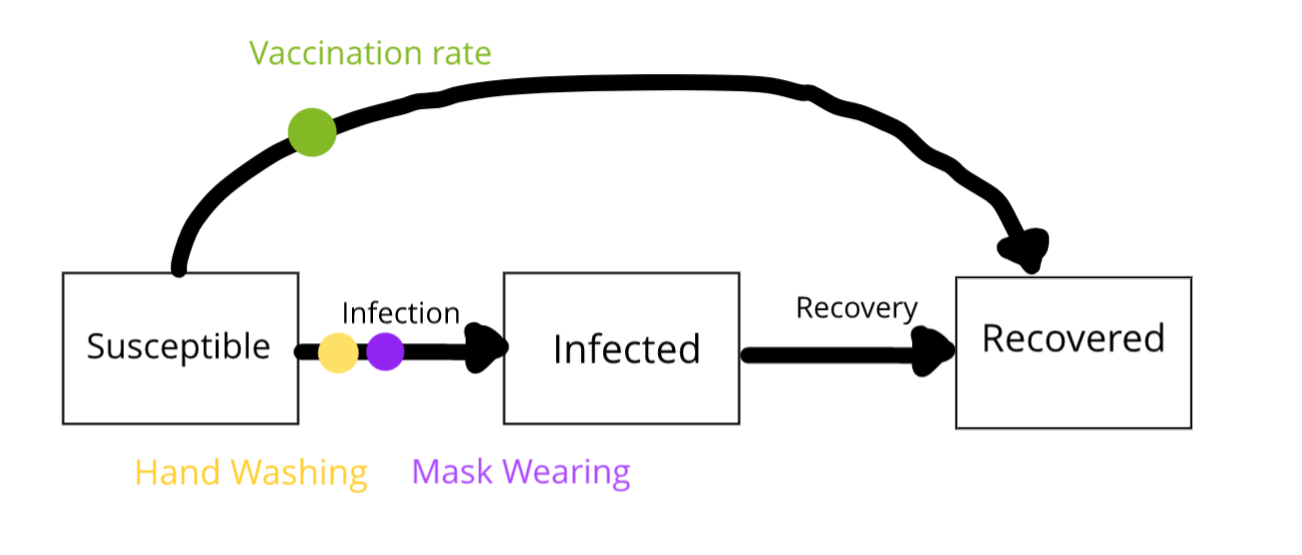

To model the effects of the different potential health measures, seperate functions were written as versions of the original sir_simulate and sir_step, modified to account for the impact of the health measures on the spread of the virus. 

Then, the simulate functions were encoded into a print function called* PlotMaster*, where the number of infected individuals were plotted over a time in weeks for each simulation of the first wave for each implemented health measure (or lack thereof). 

We also coded a second wave into the model, but decided against including it within the final model because we felt that it strayed too far from answering the original prompt question.

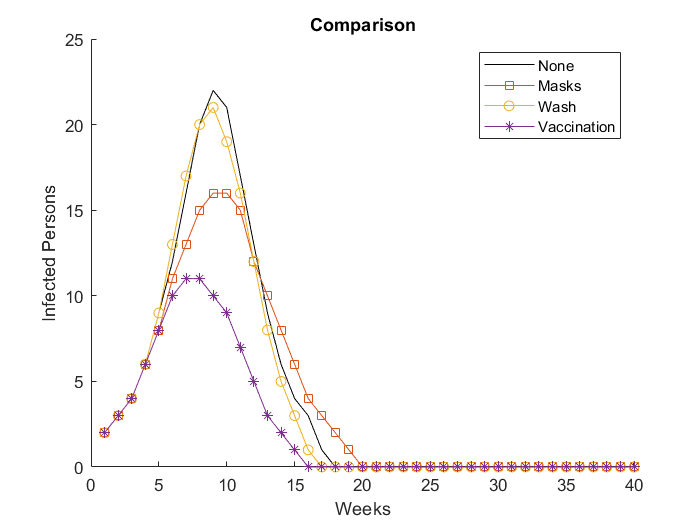

% Wave 1 - Mutagen v.1
% Defines Rates of Transfer (Flows)
beta = 1/90; % Infection Rate
gamma = 1/2; % Recovery rate in 1/weeks
masks = 1/10; % 10% of population wearing masks
wash = 1/10; % 10% of population frequently washing hands
vaccine = 50/100; % A flu vaccine with an average prevention rate of 50%
dose = 1/10; % 10% of population vaccinates
i_0 = 2; % Number of initial infections

population = 100;
s_0 = population - i_0;
r_0 = 0; 

num_steps = 40; % Number of Weeks Simulated

[S,I,R,W]=sir_v1_simulate(s_0, i_0, r_0, beta, gamma, num_steps);

figure(1); clf; hold on;
plot(W,I,'k-'); label1 = "None";

[S,I,R,W]=sir_v1_simulate_mask(s_0, i_0, r_0, beta, gamma, num_steps, masks);

plot(W,I,'s-'); label2 = "Masks";

[S,I,R,W]=sir_v1_simulate_wash(s_0, i_0, r_0, beta, gamma, num_steps, wash);

plot(W,I,'o-'); label3 = "Wash";

[S,I,R,W]=sir_v1_simulate_vax(s_0, i_0, r_0, beta, gamma, num_steps, vaccine, dose);

plot(W,I,'*-'); label4 = "Vaccination";

xlabel("Weeks")
ylabel("Infected Persons")
legend({label1, label2, label3, label4})
title("Comparison")

In order to verify the model, we did two things;

- We made sure we weren't losing any people, we plotted the total number of humans over time, demonstrated below;

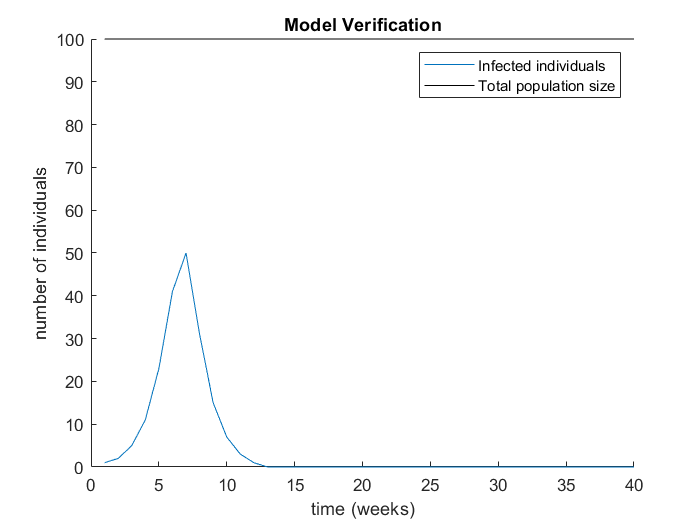

beta = 1/50; % Infection Rate
gamma = 1/2; % Recovery rate in 1/weeks
population = 100;
i1_0 = 1; % Number of initial infections
s1_0 = population - i1_0;
r1_0 = 0; 
%masks = 1/5;
num_steps = 40; % Number of weeks Simulated
figure(1); clf; hold on
    [S,I,R,W]=sir_v1_simulate(s1_0, i1_0, r1_0, beta, gamma, num_steps);
    plot(W,I);
    total = I + R + S;
    plot (W, total, 'k-')
    xlabel ("time (weeks)")
    ylabel ("number of individuals")
    legend(["Infected individuals","Total population size"]);
    title("Model Verification")
hold off

         2. We then conducted a sensitivity analysis on the different health measures by doing paramater sweeping of the variables, demonstrated below;

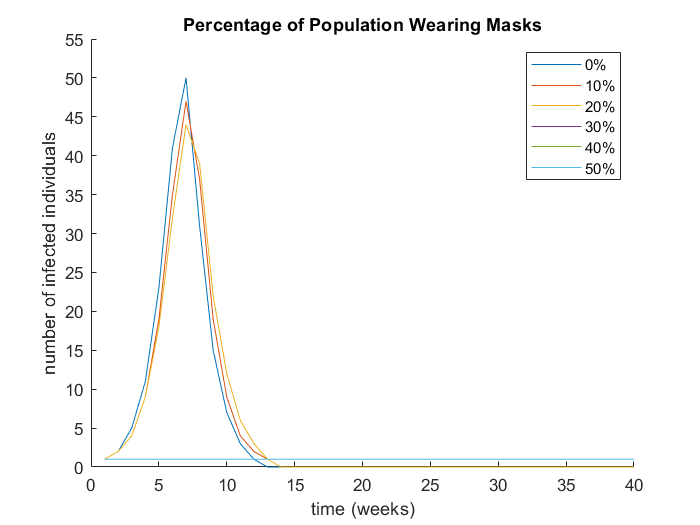

%PARAMATER SWEEPING FOR MASKS
beta = 1/50; % Infection Rate
gamma = 1/2; % Recovery rate in 1/weeks
population = 100;
i1_0 = 1; % Number of initial infections
s1_0 = population - i1_0;
r1_0 = 0; 
num_steps = 40; % Number of weeks Simulated
figure(1); clf; hold on

for masks = 0.0:0.1:0.50
    [S,I,R,W]=sir_v1_simulate_mask_sweep(s1_0, i1_0, r1_0, beta, gamma, num_steps, masks);
    plot(W,I);
    xlabel ("time (weeks)")
    ylabel ("number of infected individuals")
end
legend(["0%","10%","20%","30%","40%","50%"]);
title("Percentage of Population Wearing Masks")
ylim([0 55])
hold off

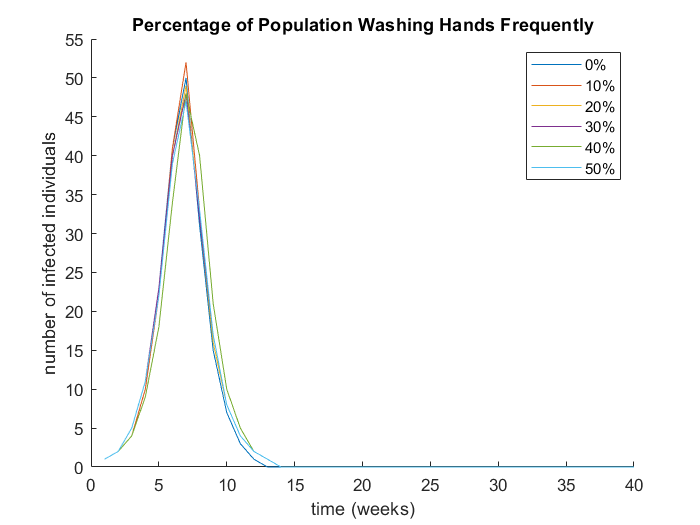


%PARAMATER SWEEPING FOR HANDWASHING
beta = 1/50; % Infection Rate
gamma = 1/2; % Recovery rate in 1/weeks
population = 100;
i1_0 = 1; % Number of initial infections
s1_0 = population - i1_0;
r1_0 = 0; 
%masks = 1/5;
num_steps = 40; % Number of weeks Simulated
figure(1); clf; hold on

for wash = 0.0:0.1:0.50
    [S,I,R,W]=sir_v1_simulate_wash(s1_0, i1_0, r1_0, beta, gamma, num_steps, wash);
    plot(W,I);
    xlabel ("time (weeks)")
    ylabel ("number of infected individuals")
end
title("Percentage of Population Washing Hands Frequently")
ylim([0 55])
legend(["0%","10%","20%","30%","40%","50%"]);
hold off

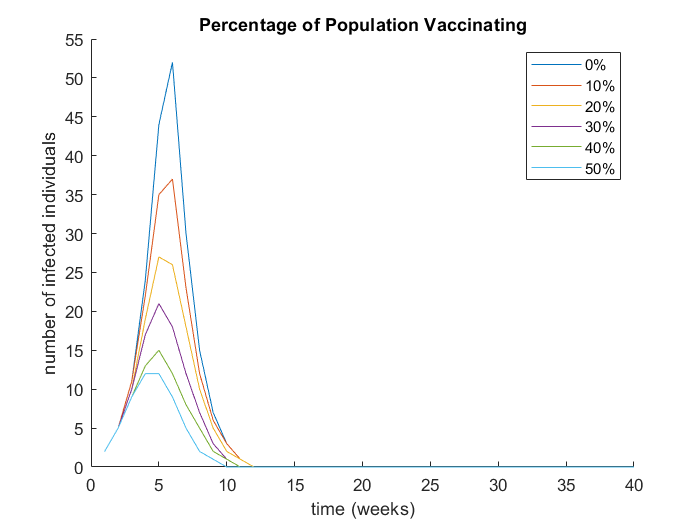


%PARAMETER SWEEPING FOR HANDWASHING
beta = 1/50; % Infection Rate
gamma = 1/2; % Recovery rate in 1/weeks
population = 100;
i1_0 = 1; % Number of initial infections
s1_0 = population - i1_0;
r1_0 = 0; 
vaccine = 50/100;
%dose = 5/100;
num_steps = 40; % Number of weeks Simulated
figure(1); clf; hold on

for dose = 0.0:0.1:0.50
    [S,I,R,W]=sir_v1_simulate_vax(s_0, i_0, r_0, beta, gamma, num_steps, vaccine, dose);
    plot(W,I);
    xlabel ("time (weeks)")
    ylabel ("number of infected individuals")
end
title("Percentage of Population Vaccinating")
ylim([0 55])
legend(["0%","10%","20%","30%","40%","50%"]);
hold off

The effectiveness of each of these variables was assigned based on values from reaserch on their effects on similar virus'. For example, one [study](https://www.thelancet.com/journals/lancet/article/PIIS0140-6736(20)31142-9/fulltext) found that mask wearing decreases the risk of infection to those wearing masks by 65%. Frequent handwashing has been found to decrease the risk of infection by between [16%](https://www.cdc.gov/handwashing/why-handwashing.html) - [36%](https://wellcomeopenresearch.org/articles/5-98/v1). Lastly, vaccination effectiveness was chosen to be the [average effectiveness](https://www.cdc.gov/flu/vaccines-work/vaccineeffect.htm#:~:text=While%20vaccine%20effectiveness%20(VE)%20can,matched%20to%20the%20flu%20vaccine.) of a well-matched vaccine.

## Result

Given the prompt and the model we created, we were able to crudely compare the impacts of vaccination, hand-washing, and mask-wearing on the general infection rate of a population of 100. Many variables (such as infection and recovery rate, the impact of the various public health measures such as vaccination efficiency) were somewhat overgeneralized, within subjectively determined reasonable ranges, and remain unvalidated, but verified.

By visualising our model's results, we are able to conclude that vaccination is by far the most effective public health measure, with mask-wearing coming in second, and hand-washing last, per capita.

## Interpretation

The model we created contains many assumptions and has several limitations in applicability. We've listed them below here for your consideration:

- For the continued simplicity of the model, our group decided to avoid detecting edge cases such as immunodeficiency or supercarriers/spreaders.

- There is a strange outlier in the 50% sweep of the mask wearing population that we cannot, at this point in time, explain.

- We were unable to validate our model using training data, due to the very nature of the assignment. 

- We established arbitrary infection & recovery rates, using subjective intuition.

- We generalized data on the reduction of spread of respiratory illnesses via mask-wearing, using information from studies on COVID, with the assumption that mask wearing would function similarly to other respiratory viruses.

- We placed the public health measures into separate sub-programs instead of collating them, which makes it difficult to project combined public health measure interaction & effect.

- We generalized data on the effectiveness of vaccinations, based off of the CDC's data.